# Thermo 2019 chapter 3 - Part B 

detailed corrections

format short; rho_w=1000; c_w=4180; %J/K/kg
L_vap_w=2257e3; %J/kg
R=8.31; Cv=20.8; Cp=29.1; % diatomic

## **Exo 3.7 : Veron’s Cycle**

10 moles of a diatomic ideal gas are processed along a reversible cycle. 

Initially (state A) the gas is under a pressure of 100 atm at temperature of 300 K. 

---------------------

**Guide for the correction of this exercice** : *We see in the exercise statement that the number of moles is constant since the gas is embedded into a closed device. The system that we consider is the *$n$* moles of gas. The cycle is reversible, which means that at any time the surrounding variables are identical to the variables of the system e.g. *$T_{ext}=T$*, *$P_{ext}=P$*.*

*--------------------*

**1) **Calculate the volume $V_A$ of the gas.

we know that the number of moles $n=10$, say the pressure and the temperature at state A :$P_A =100\;\textrm{atm}$, $T_A =300\;\mathrm{K}$

The volume can be calculated applying the ideal gas law :


$$V_A =\frac{\textrm{nR}T_A }{P_A }$$


n=10; Cv=20.8; R=8.314; Cp=R+Cv;g=Cp/Cv; PA=100; TA=300; atm=101325;
VA=n*R*TA/(PA*atm); fprintf('VA = %2.2f L',VA*1e3) % in m^3

VA = 2.46 L

**2) **Calculate the volume $V_B$ after an isothermal expansion until pressure $P_B=10\,\mathrm{atm}$. Calculate the quantities $W_1$ and $Q_1$transferred to the gas by the surroundings during the process A→B.

Isothermal expansion to $P_B =10\;\textrm{atm}$, therefore both $n$ and $T$ are constant, which can be written as : 

     
$$P_A V_A =P_B V_B \iff V_B =\frac{P_A V_A }{P_B }$$


The elementary work is $\delta W_1=-P_{ext}dV$ where the surrounding pressure $P_{ext}$ is always equal to pressure of the system $P$, therefore the former relation

    ${\delta W}_1 =-P\left(V\right)\mathrm{dV}$  where $P(V)=\frac{nRT_A}{V}$  substituting leads to : ${\delta W}_1 =-\frac{\mathrm{nR}T_A }{V}dV$

            
$$\iff W_1 =-nRT_A \mathrm{ln}\frac{V_B }{V_A }$$


This is an isothermal process ($T=Cte$) and the internal energy of an ideal gas depends only on the temperature, isotherme then ${\Delta U}_1 =0\iff Q_1 =-W_1$

PB=10; VB=PA*VA/PB; TB=TA;
W1=n*R*TA*log(VB/VA); fprintf('W1 = %2.1f kJ',W1/1e3) % in J

W1 = 57.4 kJ

Q1=-W1; fprintf('Q1 = %2.1f kJ',Q1/1e3)

Q1 = -57.4 kJ

DU1=0; fprintf('DU1 = %2.0f kJ',DU1/1e3)

DU1 =  0 kJ

**3) **The gas is compressed by an isochoric process to the pressure 2 atm (state C). Calculate the temperature $T_C$  and the quantities $W_2$ and $Q_2$ transferred during the process B→C.

The process is isochoric, so that $V=Cte$, therefore the ideal gas law becomes $\frac{P}{T}=Cte$. Furthermore, we know that $P_C =2\;\textrm{atm}$,  then $\frac{P_B }{T_B }=\frac{P_C }{T_C }\iff T_C =T_B \frac{P_C }{P_B }$

There is no volume variation during the process, therefore the work is nil $W_2 =0$ and 

    
$$Q_2 ={\Delta U}_2 =n\bar{C_V } \left(T_C -T_B \right)$$


PC=2; TC=TB*PC/PB; fprintf('TC = %2.0f K',TC)

TC = 60 K

VC=VB;
W2=0;
DU2=n*Cv*(TC-TB); fprintf('DU2 = %2.1f kJ',DU2/1e3)

DU2 = -49.9 kJ

Q2=DU2;

**4)** In other to close the cycle, the gas is submitted to an isobaric process inducing an expansion to the state D followed by an adiabatic compression leading to the state A. Calculate first the volume VD and the temperature TD of the gas in state D and then the quantities $W_3$ and $Q_3$  corresponding to C→D and  $W_4$ and $Q_4$ corresponding to D→A.

Since the process CD is isobaric $P=Cte$ and $P_C =P_D$ However, two variables are unknown for the state D : $T_D$ and $V_D$ therefore the calculation can not be done along the CD process. It is however, followed by an adiabatic (reversible) process. We can calculate the state D from the DA process. Along a reversible process, one can write : 

    
$$PV^{\gamma } =\mathrm{Cte}\iff P_D {V_D }^{\gamma } =P_A {V_A }^{\gamma } \iff V_D ={V_A \left(\frac{P_A }{P_C }\right)}^{1/\gamma }$$


Then the temperature can be calculated along the CD isobaric process for which  :

    
$$\frac{T}{V}=Cte$$
 
$$\iff \frac{T_D }{V_D }=\frac{T_C }{V_C }\iff T_D =T_C \frac{V_D }{V_C }$$


The pressure being constant for the isobaric, $W_3 =-P_C \left(V_D -V_C \right)$  

the heat is equal to the enthaly variation : $Q_3 ={\Delta H}_3 =n\bar C_P \left(T_D -T_C \right)$ 

    and ${\Delta U}_3 =W_3 +Q_3$ 

Along an adiabatic process there is no exchanged heat, $Q_4=0$

  
$$W_4 ={\Delta U}_4 =n\bar C_V \left(T_A -T_D \right)$$


PD=PC;VD=VA*(PA/PC)^(1/g); fprintf('VD = %2.1f L',VD*1e3)

VD = 40.3 L

TD=TC*VD/VC; fprintf('TD = %2.2f K',TD)

TD = 98.16 K

W3=-PC*(VD-VC)*atm; fprintf('W3 = %2.1f kJ',W3/1e3)

W3 = -3.2 kJ

Q3=n*Cp*(TD-TC); fprintf('Q3 = %2.1f kJ',Q3/1e3)

Q3 = 11.1 kJ

DU3=W3+Q3; fprintf('DU3 = %2.1f kJ',DU3/1e3)

DU3 = 7.9 kJ

Q4=0; DU4=n*Cv*(TA-TD); fprintf('DU4 = %2.1f kJ',DU4/1e3)

DU4 = 42.0 kJ

W4=DU4;

**5)** From the calculation of the total work $W$ and total heat $Q$ check that the internal energy is indeed a state function.

One can define the work $W$ and the heat $Q$ transfered between the system and the surroundings for the whole cycle. One can write : $W=\sum_1^4 W_i$ , $Q=\sum_1^4 Q_i$  and $\Delta U=W+Q$

% this part of the code is to display the results in a table
Vi=[VA;VB;VC;VD]*1000;  % in L 
Pi=[PA;PB;PC;PD];       % in atm
Ti=[TA;TB;TC;TD];
state=['A';'B';'C';'D'];
tab=table(state,Vi,Pi,Ti) % in m^3 ; Pa ; K

tab = 4×4 table
    state      Vi      Pi       Ti  
    _____    ______    ___    ______
      A      2.4616    100       300
      B      24.616     10       300
      C      24.616      2        60
      D      40.273      2    98.164

Qi=[Q1;Q2;Q3;Q4]/1000;  % in kJ
Wi=[W1;W2;W3;W4]/1000;  % in kJ
DUi=Qi+Wi;
tab=table(Qi,Wi,DUi)

tab = 4×3 table
      Qi         Wi        DUi  
    _______    _______    ______
    -57.431     57.431         0
     -49.92          0    -49.92
     11.111    -3.1729    7.9381
          0     41.982    41.982

Let's calculate $W$, $Q$ and $\Delta U$:

fprintf('sum Wi = %1.1f kJ',sum(Wi)) % sum of the values of the table Wi

sum Wi = 96.2 kJ

fprintf('sum Qi = %1.1f kJ',sum(Qi))

sum Qi = -96.2 kJ

fprintf('sum DUi = %1.1f kJ',sum(DUi))

sum DUi = 0.0 kJ

Indeed $U$ is a state function since its variation is nil over a cycle.

**6)** Complete the Clapeyron's $P(V)$ diagram for the system  with the points: A(VA ; 100), E(4.04; 50), F(6.63; 25), G(12.7; 10), H(20.9; 5) and D(VD ; 2) and give a graphical estimation of the total work on the cycle. (Scale: 1L-4mm and 1atm-2mm)

The plot can done manuely on a paper, here it has been done using the computer, but it does not change the method. The lines of the graph $P(V)$ of the different processes can be plotted for each process 1, 2 , 3 and 4 since they are all reversible. 

**AB** is an hyperpola that can be plotted from the equation of the curve $P(V)$. For this, we just have to write the fact that $T=Cte$, which implies that $PV=Cte$$\iff PV=P_AV_A\iff P(V)=\frac{P_AV_A}{V}$.

**BC** is a vertical line, since $V=Cte$.

**CD** is an horizontal line, since $P=Cte$.

**DA** is the curve of a reversible adiabatic process, for which we have $PV^\gamma=Cte$$\iff PV^\gamma=P_A{V_A}^\gamma$ $\iff P(V)=\frac{P_A{V_A}^\gamma}{V^\gamma}$. We have seen during the lecture that at the same point, for instance in A the slope of the adiabatic $P(V)$ curve is larger (and they are negative), than that of the isothermal. Therefore in A the adiabatic curve is below the isothermal one. To make a correct plot on a paper, it is interesting to find the pressure of the adiabatic curve for the value $V_C$, which definitely shows that the adiabatic curve intercept the isochoric curve.

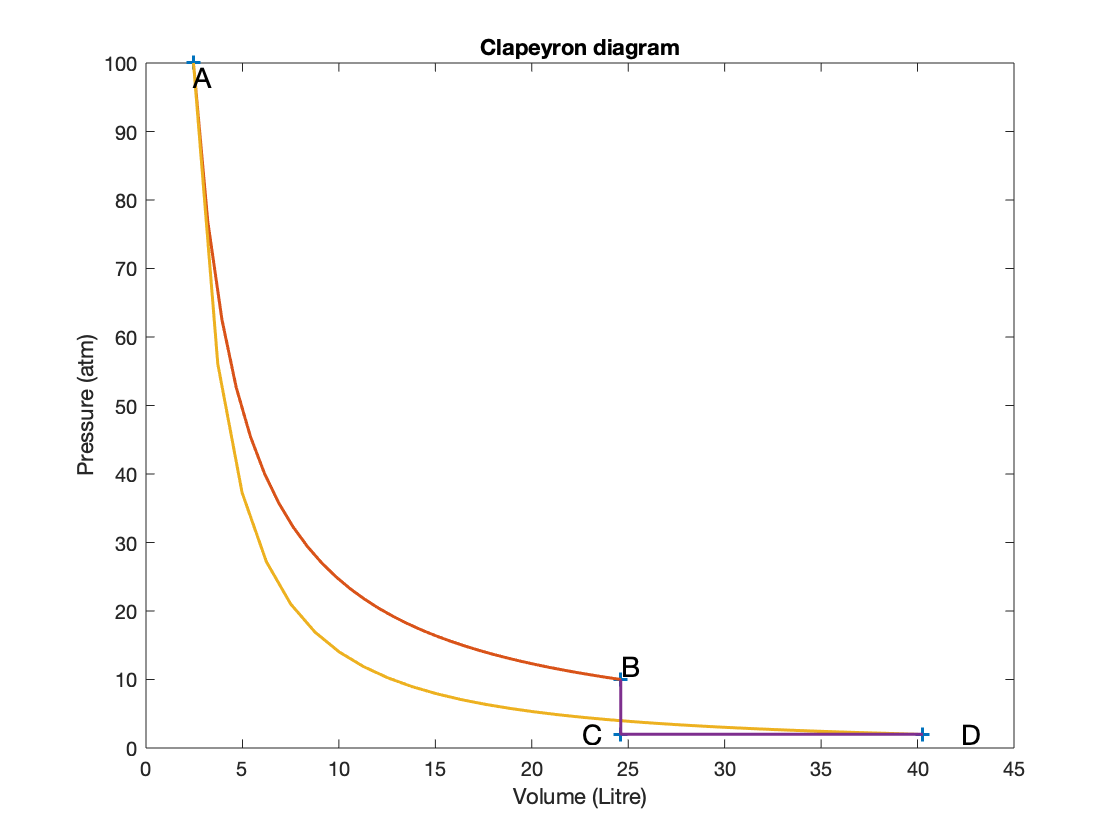

plot(Vi,Pi,'linewidth',1.5,'LineStyle','none','Marker','+') % plot of the 4 states
% de VA à VB isotherme
V1=Vi(1):(Vi(2)-Vi(1))/30:Vi(2); % vecteur des V1
P1=Pi(1)*Vi(1)./V1;              % pression des P1
% de VD à VA adiabatique
V3=Vi(4):(Vi(1)-Vi(4))/30:Vi(1);
P3=Pi(4)*Vi(4)^g./(V3.^g);
V2=[Vi(2) Vi(3) Vi(4)];
P2=[Pi(2) Pi(3) Pi(4)];
hold on
plot(V1,P1,'linewidth',1.5,'LineStyle','-','Marker','none')
plot(V3,P3,'linewidth',1.5,'LineStyle','-','Marker','none')
plot(V2,P2,'linewidth',1.5,'LineStyle','-','Marker','none')
xlabel('Volume (Litre)')
ylabel('Pressure (atm)')
title('Clapeyron diagram')
text(Vi(1),Pi(1)-2,'A','FontSize',14)
text(Vi(2),Pi(2)+2,'B','FontSize',14)
text(Vi(3)-2,Pi(3),'C','FontSize',14)
text(Vi(4)+2,Pi(4),'D','FontSize',14)
hold off

**That part corresponds to the exercise 4.5 which consists in fact into the follow up of this exercise.**

**7) **Calculate the entropy variations $\Delta S_1$, $\Delta S_2$, $\Delta S_3$ and $\Delta S_4$ of the gas, corresponding to the different processes (isothermal, isochoric, isobaric and adiabatic) 

AB : isothermal, therefore $T=Cte=T_A$, ${\textrm{dS}}_1 =\frac{\delta Q_1 }{T_A }\iff {\Delta S}_1 =\frac{Q_1 }{T_A }=\frac{-W_1 }{T_A }=\textrm{nRln}\frac{V_B }{V_A }$

BC : sochoric : ${\textrm{dS}}_2 =\frac{\delta Q_2 }{T}=\frac{n{\bar{\mathrm{C}} }_V \textrm{dT}}{T}\iff {\Delta S}_2 =n{\bar{C} }_V \ln \frac{T_C }{T_B }$

CD : isobaric : ${\textrm{dS}}_3 =\frac{\delta Q_3 }{T}=\frac{n{\bar{C} }_P \textrm{dT}}{T}\iff {\Delta S}_3 =n{\bar{C} }_P \ln \frac{T_D }{T_C }$

DA : reversible adiabatic : ${\Delta S}_4 =0$

DS1=n*R*log(VB/VA);DS2=n*Cv*log(TC/TB);DS3=n*Cp*log(TD/TC);DS4=0;
DSi=[DS1 DS2 DS3 DS4]

DSi =   191.4369 -334.7631  143.3262         0


**8. **Check that entropy is a state function and plot the (*T*, *S*) diagram representing the cycle

If we define the enropy varition $\Delta S$ of the system, such that $\Delta S =\sum_{i=1}^{4} \Delta S_i$ and make the numerical calculation, we that it is nil over a cycle, showing that the entropy of the system is a state function

fprintf('sum DSi = %1.1f JK^-1',sum(DSi))

sum DSi = 0.0 JK^-1

There is a slight difference in that plot $T(S)$ as compared to for instance the Clapeyron's diagram $P(V)$, since we have only calculated entropy variations, for instance the variation between states A and B. We don't know the value of the entropy at a give state, which also means that we only know the value to a constant. Therefore we need to find a reference state point, for instance A for which we arbitrally fix the entropy to 0. As for the Clapeyron's diagram, we need to define the different curves :

**AB** : isothermal, so that the temperature is constant, therefore we have an horizontal line that starts in A, such that $S_A=0$ and since $\Delta S_{AB}=+191\,\mathrm{JK^{-1}}$, the point B will have the arbitrary value $S_B=191\,\mathrm{JK^{-1}}$.

**BC **: isochoric, neither $T$ nor $S$ are constant, so that one needs to establish the curve $T(S)$. For this , one can write the definition of the entopy between the point B and a given point X located between B and C, so that $dS_{BX}=\frac{\delta Q}{T}=\frac{n\bar C_vdT}{T}$ $\iff \Delta S_{BX}=n\bar C_v \ln\frac{T_x}{T_B}$ $\iff T_x=T_B\exp\frac{\Delta S_{BX}}{n\bar C_v}$, this represents the curve of the funtion $T_x=f(\Delta S_{BX})$.

**CD** : isobaric, again neither $T$ nor $S$ are constant, so that one needs to establish the curve $T(S)$, Considering the same methodology for a given point X between C and D, one can write : $dS_{CX}=\frac{\delta Q}{T}=\frac{n\bar C_pdT}{T}$ $\iff \Delta S_{CX}=n\bar C_p \ln\frac{T_x}{T_C}$ $\iff T_x=T_C\exp\frac{\Delta S_{CX}}{n\bar C_p}$

**DA **: Over the adiabatic process the entropy variation $\Delta S_{DA}=0$, therefore the curve is a vertical straigth line.

Both curves BC and CD are described by similar function, where the difference, is $\bar C_p$ or $\bar C_v$ on the denominator, their shape are therefore close, and when trying to plot both curbes at the same point C, one may find out the relative values of the derivates, that are : ${\Big(\frac{dT}{dS}\Big)}_V=\frac{T}{n\bar C_v}$ and ${\Big(\frac{dT}{dS}\Big)}_P=\frac{T}{n\bar C_p}$. Since $\bar C_p>\bar C_v$, then the slope of isochoric curve is larger.

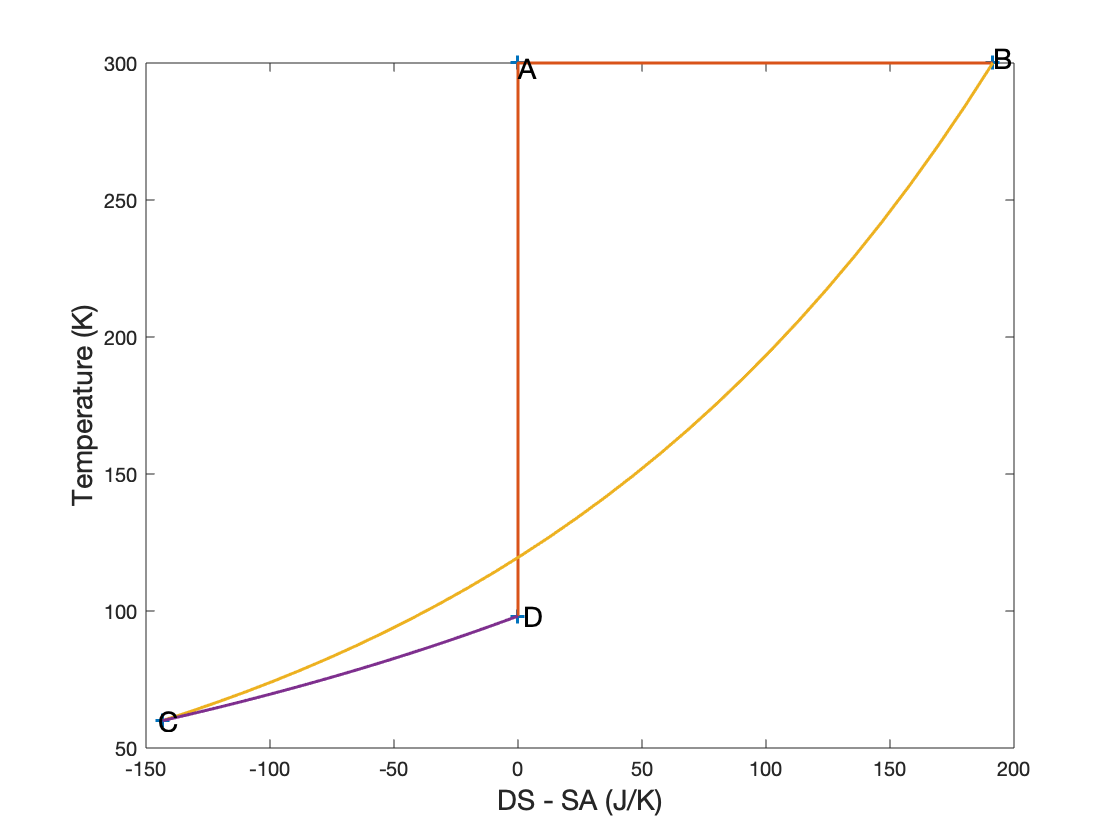

Si=[0 DS1 DS1+DS2 DS1+DS2+DS3];
figure
plot(Si,Ti,'linewidth',1.5,'LineStyle','none','Marker','+') % plot of the diff states
T1=[Ti(4) Ti(1) Ti(2)]; % tracé adiabatic et isotherme
S1=[Si(4) Si(1) Si(2)];
hold on
plot(S1,T1,'linewidth',1.5,'LineStyle','-','Marker','none')
S2=Si(2):(Si(3)-Si(2))/30:Si(3);
T2=Ti(2).*exp((S2-Si(2))./(n*Cv));
plot(S2,T2,'linewidth',1.5,'LineStyle','-','Marker','none')
S3=Si(3):(Si(4)-Si(3))/30:Si(4);
T3=Ti(3).*exp((S3-Si(3))./(n*Cp));
plot(S3,T3,'linewidth',1.5,'LineStyle','-','Marker','none')
xlabel('DS - SA (J/K)','FontSize',14)
ylabel('Temperature (K)','FontSize',14)
text(Si(1),Ti(1)-2,'A','FontSize',14)
text(Si(2),Ti(2)+2,'B','FontSize',14)
text(Si(3)-2,Ti(3),'C','FontSize',14)
text(Si(4)+2,Ti(4),'D','FontSize',14)
hold off

DS=sum(DSi); fprintf('DS = %2.1f J/K',DS)

DS = 0.0 J/K

## **Exo 3.9 : Adiabatic expansion**

Ten litters of a di-atomic gas contained in a cylinder-piston device is submitted to an adiabatic expansion. The initial temperature and pressure are ( $0°C$ and $10\,\mathrm{atm}$ ) and the final pressure is $1\,\mathrm{atm}$.

Calculate the final volume and temperature and the work supplied when the process is :

**a) **    reversible

A reversible process means that the state variables of the system are known at any time, which also means that one can obtain function, $P(V), V(T) , T(P)$ functions. In order to obtain such a function one needs to write an differential equation describing the system and integrate it. An adiabatic process is for nil heat transfer, therefore :

$\delta Q=0$ $\iff dU=\delta W$$\iff n\bar C_vdT=-PdV$ (reversible)

In this above equation, we have the variables $P,T$ and $V$, therefore we need to get rid off one of these variables, for instance $P$, which gives us an equation of only the $V$ and $T$ variables, as seen during the lecture. 

As an exercice, we are going to do it differently replacing $T$ and in fact $dT$ as a function of the variables $V$ and $P$. For this  use the state function of the ideal gas law : $T=\frac{PV}{nR}$ giving the differential : $dT=\frac{PdV+VdP}{nR}$, that we can substitute into the above equation leading to :

    $\frac{\bar C_v}{R}(PdV+VdP)=-PdV$, which can be rearranged as :

    
$$\frac{\bar C_v}{R}VdP=-(1+\frac{\bar C_v}{R})PdV$$
 
$$\iff \bar C_v\frac{dP}{P}=-(R+\bar C_v)\frac{dV}{V}$$
 
$$\iff -\frac{\bar C_v}{R+\bar C_v}\frac{dP}{P}=\frac{dV}{V}$$


Since $R+\bar C_v=\bar C_p$, then $\frac{\bar C_v}{R+\bar C_v}=\frac{1}{\gamma}$ then substituting in the above equation one obtains :

    $-\frac{1}{\gamma}\frac{dP}{P}=\frac{dV}{V}\iff \frac{dP}{P}=-\gamma\frac{dV}{V}$ this equation can be integrated as :

    
$$\ln P=-\gamma\ln V+Cte$$

$$\iff PV^\gamma=\exp Cte\iff PV^\gamma=Cte$$
 

Let's apply this equation as :

$P_i{V_i}^\gamma=P_f{V_f}^\gamma$ $\iff V_f=V_i\Big(\frac{P_i}{P_f}\Big)^{1/\gamma}$ with  $V_i=10\,\mathrm{L}$, $P_i=10\,\mathrm{atm}$, $T_i=0°\mathrm{C}$ and $P_f=1\,\mathrm{atm}$

We can calculate the temperature applying the ideal gas law for a constant number of moles :

    
$$\frac{P_iV_i}{T_i}=\frac{P_fV_f}{T_f}$$
  
$$$\iff T_f=T_i\frac{P_f}{P_i}\frac{V_f}{V_i}$$


The process being adiabatic $\delta Q=0$ therefore $\delta W=
dU=n\bar C_vdT$ $\iff W=n\bar C_v(Tf-Ti)$

Note that the work could also be calculated from the work definition :

    $\delta W=-P_{ext}dV\iff \delta W=-P(V)dV$ (since reversible), and as shown above $P(V)=\frac{P_i{V_i}^\gamma}{V^\gamma}$ subtituting the the last relation leads to : $\delta W=-P_i{V_i}^\gamma \frac{dV}{V^\gamma}$, which can be integrated as :

    $W=\frac{-P_i{V_i}^\gamma}{1-\gamma}({V_f}^{1-\gamma}-{V_i}^{1-\gamma})$ we check below that the result is the same but ideed the calculation is more complex.

R=8.31; Cv=20.8; Cp=29.1; gamma=Cp/Cv;
Vi=10e-3; Pi=10e5; Ti=273; Pf=1e5; 
Vf=Vi*(Pi/Pf)^(1/gamma); fprintf('Vf = %2.1f L',Vf*1e3)  % in m^3
Tf=Ti*Pf/Pi*Vf/Vi; fprintf('Tf = %2.0f K',Tf)        % in K
W=(Pi*Vi/R/Ti)*Cv*(Tf-Ti); fprintf('W = %2.1f kJ',W/1e3) % in J
W=-Pi*Vi^gamma/(1-gamma)*(Vf^(1-gamma)-Vi^(1-gamma)); fprintf('W = %2.1f kJ',W/1e3) % in J

**b)**     an abrupt expansion against a constant atmospheric pressure (1.00 atm).

Since this is this time an abrupt variation, the process is not reversible, which means that the state variables of the system are not defined all along the cycle, which means that we can not define a $P(V), T(V)...$ law. We can therefore ony consider the variation of the different quantities between the final and the initial states.

This is still an adiabatic process sot that $Q=0$ which means that $W=\Delta U$

We can replace the work and the internal energy variation by the usual expressions $W=-P_{ext}(V_f-V_i)$ and $\Delta U=n\bar C_v(Tf-T_i)$ which leads to :

    
$$-P_{ext}(V_f-V_i)=n\bar C_v(Tf-T_i)$$

$$\iff -P_{ext}V_f+P_{ext}V_i =n\bar C_vTf-n\bar C_vTi$$


It is mentionned in the text that the final pressure is $P_f$ and it is equal to the surrounding pressure since the system is at equilibrium in the final state, therefore $P_f=P_{ext}$

We can apply the ideal gas law so that :  $n\bar C_vT_f=\frac{P_fV_f}{R}\bar C_v$ and $n\bar C_vT_i=\frac{P_iV_i}{R}\bar C_v$

substituting in the former equation leads to

    
$$-P_fV_f+P_fV_i =\frac{P_fV_f}{R}\bar C_v-\frac{P_iV_i}{R}\bar C_v$$
 
$$\iff V_fP_f\Big(-1-\frac{\bar C_v}{R}\Big)=-P_fV_i-P_iV_i\frac{\bar C_v}{R}$$



$$$\iff V_f=\frac{P_fV_i+P_iV_i\frac{\bar C_v}{R}}{P_f\Big(1+\frac{\bar C_v}{R}\Big)}$$


P_ext=1e5; P_f=P_ext;
Vf=(P_f*Vi+Pi*Vi*(Cv/R))/(P_f*(1+Cv/R)); fprintf('Vf = %2.1f L',Vf*1e3)  % in m^3
Tf=Ti*P_ext/Pi*Vf/Vi; fprintf('Tf = %2.0f K',Tf)      % in K

Vf = 51.9 L

W=(Pi*Vi/R/Ti)*Cv*(Tf-Ti); fprintf('W = %2.2f kJ',W/1e3) % in J

Tf = 142 K

Compared to the reversible adiabatic process, the abrupt one leads to a larger final volume and less cold temperature, and a work supplied to the surroundings smaller, which means that the expansion is less efficient.

## Exo 3.10 **Study of a heat pump : a skating rink.**

A refrigeration device is mainly constituted (cf. figure) of:

- a compressor C to compress the gaseous refrigerant fluid, supplying then a work $| W|$.

- a condenser C' connected to the high temperature reservoir $\sigma_1$ consisting of running water. In the condenser, the refrigerant gas liquefies at temperature $T_1$ supplying $| Q_1|$ to $\sigma_1$.

- an expander D that consists of a valve more or less open. The refrigerant liquid is submitted to a pressure drop inducing a decrease of temperature ($W\prime=0$).

- an evaporator E related to the low temperature reservoir $\sigma_2$ consisting in the water of the skating rink. In the evaporator liquid refrigerant evaporates at temperature $T_2$, receiving $| Q_2|$ from $\sigma_2$ .

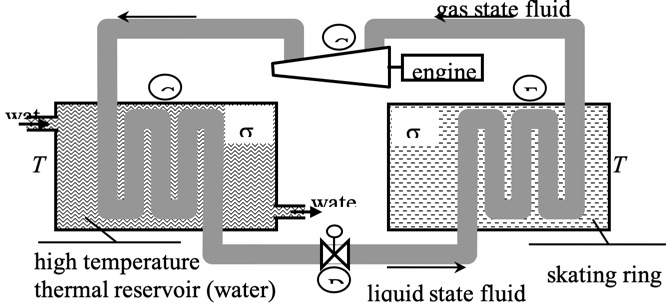

The power of the compressor is 400 hp (1hp = 736W) and the temperatures are $T_1=298\,\mathrm{K}$ and $T_2=268\,\mathrm{K}$.

**1) **Define the system and give the sign of $W$, $Q_1$ , $Q_2$  (counted for the system). Establish the relation between these quantities.

The purpose is to cool the ice, this is a refrigeration, so that $W>0$, the heat to collect from the ice is $Q_2>0$ and $Q_1<0$

**2)** Give the definition of the coefficient of performance of this device.

The coefficient of performance is the ratio of the useful energy (here $Q_2$) to the paid energy (here $W$) therefore :

    
$$Cop=\frac{Q_2}{W}$$


**3)** In the ideal case, the coefficient of performance is $CoP_{max}=8.9$. Give a numerical value of the work per hour $\dot W$ in Joules and calculate the energy taken $\dot Q_{2,rev}$ from the low temperature reservoir $\sigma_2$ per hour. 

The ideal case, means a reversible behaviour, over a cyclic behaviour. We can write the first and the second law as :

    $\Delta U=W+Q_1+Q_2=0$     (1)

    $\Delta S_\sigma=0=S_e+S_i$ with $S_i=0$ so that  $S_E=0\iff\frac{Q_1}{T_1}+\frac{Q_2}{T_2}=0$     (2)

   From (2) $Q_1=-Q_2\frac{T_1}{T_2}$, which substituted in (1) leads to $W+Q_2\big(1-\frac{T_1}{T_2}\big)=0$ $\iff \frac{Q_2}{W}=\frac{T_2}{T_1-T_2}$

Written in therms of heat flow : $\frac{\dot Q_{2,rev}}{\dot W}=\frac{T_2}{T_2-T_1}$

T1=298; T2=268; W=400*736; % W in J/s

W = -12.1 kJ

cop=T2/(T1-T2); fprintf('cop = %1.2f',cop)

W = -12.1 kJ

Q2=cop*W; fprintf('Q2 = %1.2e J/h',Q2*3600)   %J/s

**4) **The real value of this energy taken per hour from  is $\dot Q_{2,real}=3.66\times10^6\,\mathrm{kJh^{-1}}$. Calculate the real CoP :  $CoP_{real}$ compare to the ideal case and comment.

The definition of the Cop is the same : $Cop_{real}=\frac{\dot Q_{2,real}}{\dot W}$

Q2_real=3.66e9/3600; %J/s
cop_real=Q2_real/(W); fprintf('cop_real = %1.2f',cop_real)

Vf = 74.3 L

**5)** Before solidification the water of the skating rink ($\sigma_2$) presents a surface of $1800\,\mathrm{m^2$ for a thickness of $4\,\mathrm{cm}$. Given the latent fusion heat of water equal to 334.4 kJ.kg-1 and neglecting the time for cooling the water from 20°C to 0°C calculate the solidification duration of the water.

The surface of the rink is $S_r=1800\,\mathrm{m^2}$ its thickness is $t_r=4\,\mathrm{cm}$ the latent fusion heat of water is $L_w=334.4\,\mathrm{kJkg^{-1}}$, and water density : $\rho_w=1000\,\mathrm{kgm^{-3}}$.

The time for solidifying the water is $t=\frac{\rho_wS_rt_rL_w}{Q_{2,real}}$

Sr=1800; tr=4e-2; L_w=334.4e3; rho_w=1000;

Tf = 203 K

t=rho_w*Sr*tr*L_w/Q2_real; fprintf('t = %1.2f h',t/3600)

W = -6.43 kJ

**6) **The compressor works 3 hours per day to maintain the ice solid. Heating the different rooms of the skate rink requires 1000 L of oil per day (1 L of oil supplies $3.5\times 10^7\,\mathrm{J}$). Calculate the quantity of oil that could be daily saved if the heat quantity $| Q_{1,3hours}|=Q_{2,3hours}+W_{3 hours}$ corresponding to the 3 hours of daily work was used to heat some of the buildings of the skate rink.

Let's call the heat power of oil $E_{oil}=3.5\times10^7\,\mathrm{JL^{-1}}$ and the quantity of oil required to heat the rooms : $V_{oil}=1000\,\mathrm{L}$.

The energy required to heat up is therefore : $E_{req}=E_{oil}V_{oil}$.

The energy quantity brought by the heat machine is $(\dot Q_{2,real}+\dot W)t_{3h}$

therefore the quantity of oil saved per day is : $V_{save}=\frac{(\dot Q_{2,real}+\dot W)t_{3h}}{E_{oil}}$

E_oil=3.5e7; V_oil=1000; t_3h=3*3600;
V_save=((Q2_real+W)*t_3h)/E_oil; fprintf('V_save = %1.0f L',V_save)

cop = 8.93

The refrigerant fluid used was $\mathrm{12CF_2Cl_2}$ freon (molar mass 121 g.mol-1and thermal capacities in gaseous state : $c_p=611\,\mathrm{JK^{-1}kg^{-1}$ and $c_v=531\,\mathrm{JK^{-1}kg^{-1}$ ( $\gamma=1.15$). *Like all CFCs, the **CF**2**Cl**2** freon** contributes to ozone depletion in the stratosphere, and is therefore banned by the Montreal Protocol. The CFCs are now being replaced with other products such as hydrofluorocarbons (HFCs).*

7) The input pressure and temperature of the freon gas in the compressor are 1.25 atm and 0°C and the output temperature is 70°C. 

- a) The compression being adiabatic and reversible what is the freon pressure (considered an ideal gas) after the compression ?

Reversible adiabatic process with : $PV^\gamma=Cte$ and to obtain the relation $T(P)$, one needs to eliminate the volume in the former equation. Considering the ideal gas law : $\frac{T}{PV}=Cte\iff \frac{T^\gamma}{P^\gamma V^\gamma}=Cte$, multiplying this relaton by the above one leads to $T^\gamma P^{1-\gamma}=Cte$. which applied to the initial and final states leads to:

    
$$P_f=\Big({\frac{T_i}{T_f}}\Big)^\frac{\gamma}{1-\gamma} P_i$$


cp_freon=611; cv_freon=531; gamma_fr=cp_freon/cv_freon;

Q2 = 9.47e+09 J/h

Pi=1.25*101325; Ti=273; Tf=273+70;
Pf=(Ti/Tf)^(gamma_fr/(1-gamma_fr))*Pi; fprintf('Pf = %1.2f atm',Pf/101325)

- b) The total volume of the compressor cylinders is 80 L. Calculate the freon mass compressed for each cycle of the compressor.

The initial volume is therefore $V_i=80\times10^{-3}\,\mathrm{m^3}$. The molar mass of the Freon is $M_{freon}=121\,\mathrm{g\cdot mol^{-1}}$. The mass of freon is therefore : $m=\frac{1}{M_{freon}}\frac{P_iV_i}{RT_i}$

M_freon=121e-3; Vi=80e-3;
m=Pi*Vi/R/Ti*M_freon; fprintf('m = %1.0f g',m*1000)

cop_real = 3.45

- The rotation velocity of the compressor is 700 rounds/min. Calculate the mass of freon compressed in one hour.

Velocity of the rotation is $\omega=700\,\mathrm{rd\cdot min^{-1}}$. The total mass of freon is $m_t=\omega\cdot m\cdot t_{1h}$

omega=700/60; t_1h=3600;
mt=omega*m*t_1h; fprintf('mt = %1.2e kg',mt)

t = 6.58 h

- The latent evaporation heat of freon 12 is 159 kJ.kg-1. Calculate the energy necessary to evaporate the previous mass of freon. Comment.

$L_{freon}=159\,\mathrm{kJ\cdot kg^{-1}}$, therefore the energy is $Q_{evap}=m_tL_{freon}$

L_freon=159e3;
Q_evap=mt*L_freon; fprintf('Q_evap = %1.0f MJ',Q_evap/1e6)

V_save = 405 L

Pf = 7.15 atm

m = 540 g

mt = 2.27e+04 kg

Q_evap = 3609 MJ